# Exercise 2 : Use YoloV3 to detect fire in an image

## 1. Mark the bounding boxes in a test image to define the "ground truth"

I = imread('https://www.mathworks.com/content/dam/mathworks/images-stock-getty/GettyImages-1027447210.jpg');
gtruth = helper.annotateImage(I);

#### Preprocess the data 

The data will be rescaled so that all RGB values fall within the range [0, 1]. The image will also be resized into a [227, 227, 3] matrix, which is the size that the base model was trained on. 

Since the bounding box you drew is in the scale of the original image, it will need to be resized too. 

[I, gtruth] = helper.preprocessImage(I, gtruth, [227 227]);

#### Detect

Pass the preprocessed image to the detector. 

[predictedBboxes, scores, labels] = yolov3Detect(I, 0.01);

## 3. Compare predictions to ground truth

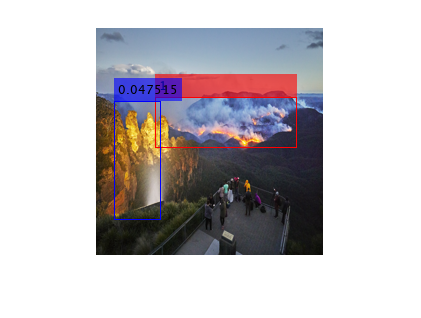

I2 = insertObjectAnnotation(I,'rectangle',gtruth, 1, 'Color', 'red');
if ~isempty(predictedBboxes)
    [~, imax] = max(scores);
    predictedBboxes = predictedBboxes(imax, :);
    scores = scores(imax);
    labels = labels(imax);    
    I3 = insertObjectAnnotation(I2,'rectangle',predictedBboxes,scores, 'Color', 'blue');
end
figure
imshow(I3)

#### How far are the detections from your hand-labeled ground truth?

We can compute the overlap ratio between the ground truth box and the predicted box. This measures the area of intersection between the boxes divided by the area of the union of the two. An overlap ratio of 0 means there is no overlap, and an overlap ratio of 1 means the bounding boxes overlap perfectly.

overlapRatio = bboxOverlapRatio(gtruth, predictedBboxes)

overlapRatio = 0.0214

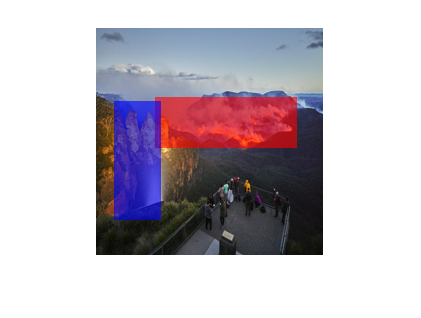

RGB = insertShape(I,'FilledRectangle',gtruth,'Color','red');
RGB = insertShape(RGB,'FilledRectangle',predictedBboxes,'Color','blue');
imshow(RGB)

#### What features were extracted from the input image?

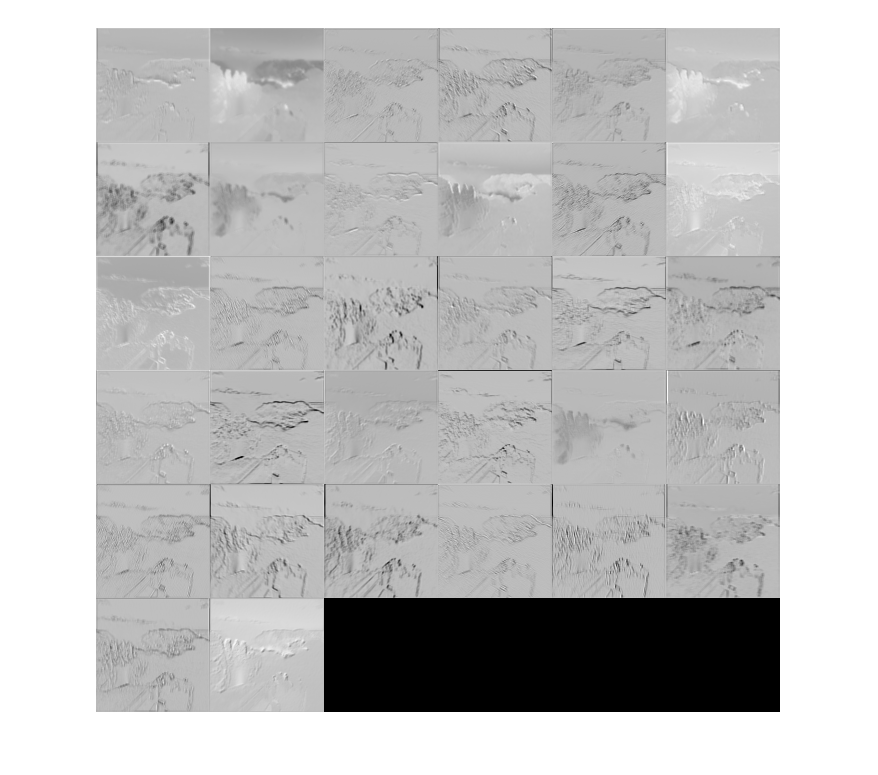

dlI = dlarray(single(imresize(I, [227 227])), 'SSCB');
conv1Activation = yolov3ExtractFeatures(dlI);
sz1 = size(conv1Activation);
conv1Activation = reshape(extractdata(conv1Activation), [sz1(1) sz1(2) 1 sz1(3)]);
ITile = imtile(mat2gray(conv1Activation));
imshow(ITile);

Show the channel with the strongest activation

[~,maxValueIndex] = max(max(max(abs(conv1Activation))))

maxValueIndex = 29

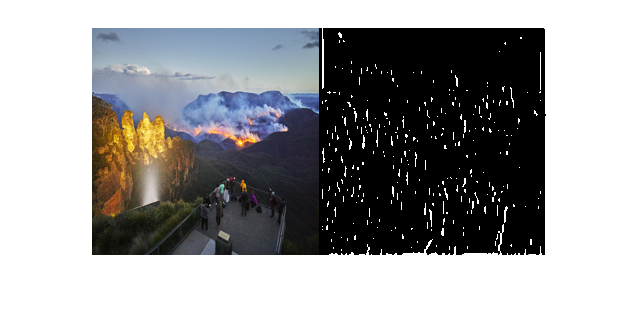

maxChannel = conv1Activation(:,:,:,maxValueIndex);
ITile = imtile({I, imresize(maxChannel, [227 227])});
imshow(ITile)